imds = imageDatastore("data", "IncludeSubfolders",true, "LabelSource","foldernames");

[imdsTrain, imdsValidation, imdsTest] = splitEachLabel(imds, 0.7, 0.25, "randomized");

audsTrain = augmentedImageDatastore([28 28], imdsTrain);
audsValidation = augmentedImageDatastore([28 28], imdsValidation);
audsTest = augmentedImageDatastore([28 28], imdsTest);

layers = [
    imageInputLayer([28 28 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',audsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

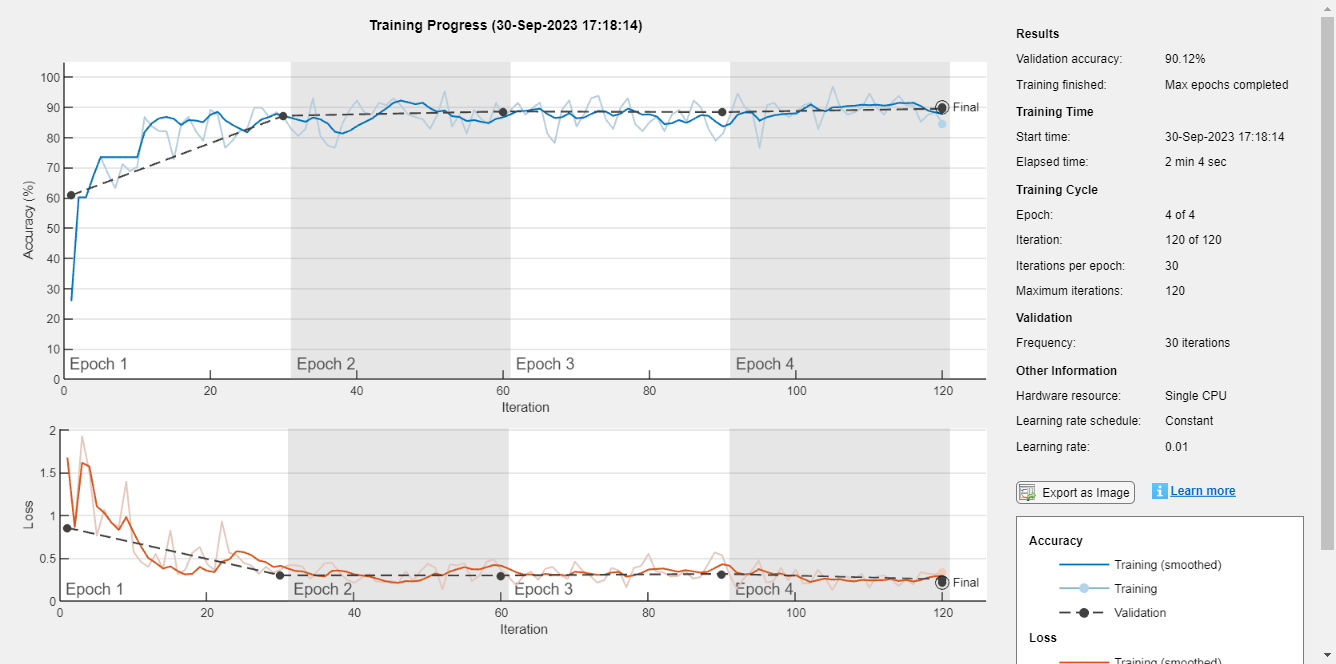

net =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


net = trainNetwork(audsTrain, layers, options)

pred = classify(net, audsTest)

pred = 282×1 categorical array
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     green_area 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     cloudy 
     water 
     cloudy 


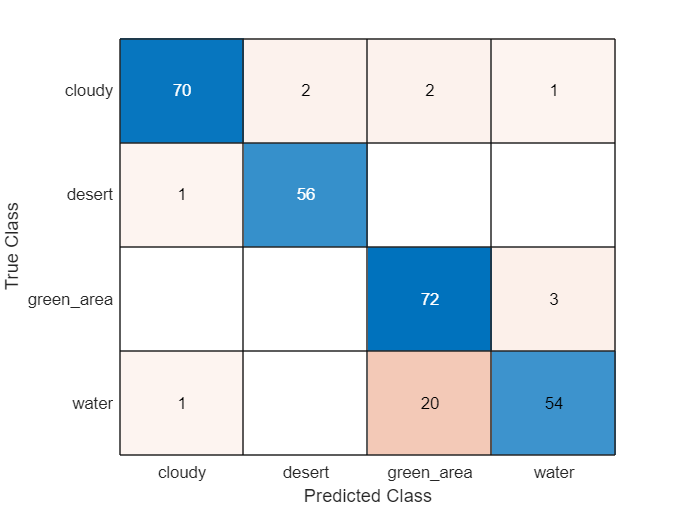


confusionchart(imdsTest.Labels, pred)


accuracy = nnz(imdsTest.Labels == pred) / size(imdsTest.Labels, 1)

accuracy = 0.8936